# German Stocks - Regression

## 1.

Load the table stored in the file `daxReturns.mat`.

load daxReturns

## 2.

Extract the index (1st variable) and stock data (other variables) into two separate `double` arrays.

stocks = daxReturns{:,2:end}

stocks =     0.0014   -0.0209   -0.0193    0.0163   -0.0127   -0.0012    0.0207   -0.0143   -0.0106   -0.0103   -0.0135   -0.0113   -0.0103   -0.0022   -0.0130   -0.0049   -0.0119    0.0118    0.0018   -0.0333   -0.0124    0.0039    0.0059    0.0063   -0.0121    0.0087   -0.0116   -0.0102   -0.0186   -0.0165
    0.0008    0.0206    0.0107    0.0267    0.0075    0.0128    0.0143    0.0157    0.0177    0.0612    0.0081   -0.0052    0.0126    0.0321    0.0166    0.0043    0.0075    0.0213    0.0217    0.0177    0.0166    0.0215   -0.0091    0.0153    0.0106    0.0179    0.0195    0.0102    0.0311    0.0057
    0.0106    0.0046    0.0106    0.0291    0.0092    0.0045    0.0114   -0.0051    0.0138   -0.0097    0.0091    0.0057    0.0024    0.0093    0.0100    0.0030    0.0044    0.0133   -0.0018    0.0339    0.0133    0.0112    0.0176    0.0081    0.0018    0.0033   -0.0805    0.0083    0.0209    0.0020
    0.0080    0.0030    0.0044   -0.0044    0.0133    0.0080   -0.0007    0.0051    0.00

index = daxReturns.DAX

index =    -0.0073
    0.0182
    0.0027
    0.0040
   -0.0022
   -0.0023
   -0.0018
    0.0086
   -0.0089
   -0.0013


## 3.

Perform a stepwise fit of all the stocks to the index returns, but using only the last 100 data points.

stpfit = stepwiselm(stocks(end-99:end,:),index(end-99:end),...
    'y ~ 1','upper','linear')

1. Adding x28, FStat = 418.5318, pValue = 3.786278e-37
2. Adding x3, FStat = 93.315, pValue = 7.27343e-16
3. Adding x26, FStat = 77.8008, pValue = 5.07492e-14
4. Adding x8, FStat = 41.2752, pValue = 5.23122e-09
5. Adding x9, FStat = 56.4026, pValue = 3.35714e-11
6. Adding x20, FStat = 25.3546, pValue = 2.32819e-06
7. Adding x24, FStat = 25.4611, pValue = 2.26268e-06
8. Adding x15, FStat = 22.2969, pValue = 8.43981e-06
9. Adding x25, FStat = 15.5114, pValue = 0.000161544
10. Adding x27, FStat = 17.6712, pValue = 6.23376e-05
11. Adding x13, FStat = 15.3981, pValue = 0.00017236
12. Adding x22, FStat = 9.2971, pValue = 0.0030407
13. Adding x4, FStat = 10.7299, pValue = 0.00152066
14. Adding x2, FStat = 15.112, pValue = 0.000200242
15. Adding x19, FStat = 10.5427, pValue = 0.00167687
16. Adding x1, FStat = 9.8288, pValue = 0.0023759
17. Adding x14, FStat = 8.3655, pValue = 0.0048953
18. Adding x6, FStat = 5.4838, pValue = 0.02165
19. Adding x11, FStat = 5.9788, pValue = 0.016675
20. Adding 

stpfit = Linear regression model:
    y ~ [Linear formula with 25 terms in 24 predictors]

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________
    (Intercept)    0.00019973    7.7073e-05    2.5914      0.011482
    x1                 0.0158     0.0062471    2.5292      0.013531
    x2               0.058782     0.0085328     6.889    1.4983e-09
    x3               0.071702     0.0093352    7.6807    4.8229e-11
    x4               0.075377     0.0098501    7.6524    5.4593e-11
    x5               0.029149      0.010581    2.7547     0.0073686
    x6                0.02743     0.0075702    3.6234    0.00052648
    x7    

## 4.

Calculate the (complete) fitted index return series of the “in model” stocks.

model = predict(stpfit,stocks)

model =    -0.0068
    0.0166
    0.0049
    0.0029
   -0.0023
   -0.0029
   -0.0018
    0.0067
   -0.0091
   -0.0000


## 5.

Plot the original and fitted return series on the same set of axes. Create a similar plot for the corresponding price series.

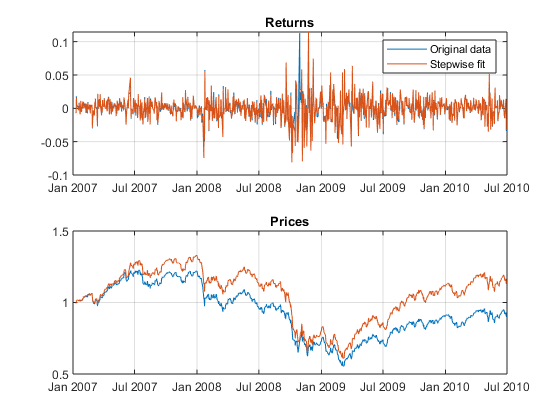

dates = datetime(daxReturns.Properties.RowNames,...
    'InputFormat','dd-MMM-yyyy');
subplot(2,1,1)
plot(dates,[index, model])
title('Returns')
legend('Original data','Stepwise fit')
grid('on')
subplot(2,1,2)
plot(dates,exp(cumsum([index, model])))
title('Prices')
grid('on')